# Solución Péndulo

y = [theta;omega]

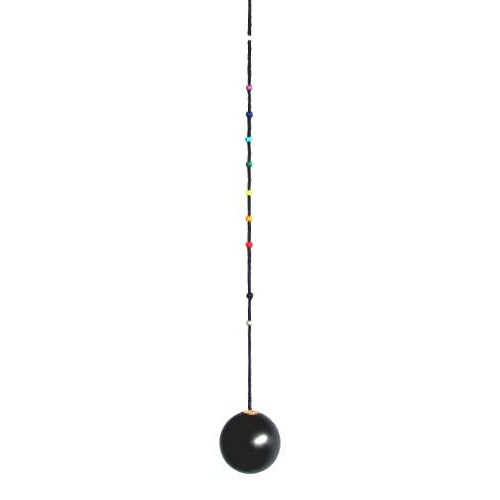

g = 9.8;
l=1;
f = @(t,y)[y(2);-(g/l)*sin(y(1))];          
y0=[pi/8;0];


[t,y] = ivps(f,0,10,y0,0.1,4)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y =     0.3927    0.3741    0.3199    0.2352    0.1279    0.0082   -0.1123   -0.2220   -0.3102   -0.3688   -0.3923   -0.3787   -0.3291   -0.2481   -0.1432   -0.0245    0.0966    0.2083    0.3000    0.3629    0.3913    0.3826    0.3376    0.2605    0.1583    0.0408   -0.0807   -0.1943   -0.2892   -0.3564   -0.3896   -0.3859   -0.3456   -0.2724   -0.1730   -0.0570    0.0646    0.1800    0.2779    0.3492    0.3872    0.3886    0.3530    0.2839    0.1875    0.0731   -0.0485   -0.1653   -0.2662   -0.3415
         0   -0.3694   -0.7052   -0.9757   -1.1540   -1.2212   -1.1697   -1.0054   -0.7458   -0.4169   -0.0501    0.3211    0.6633    0.9443    1.1363    1.2189    1.1833    1.0334    0.7851    0.4638    0.1002   -0.2724   -0.6204   -0.9113   -1.1165   -1.2146   -1.1949   -1.0595   -0.8231   -0.5099   -0.1501    0.2233    0.5764    0.8767    1.0948    1.2081    1.2043    1.0838    0.8597    0.5551    0.1997   -0.1738   -0.5315   -0.8407   -1.0713   -1.1995   -1.2116   -1.1063   -0.8949   -0

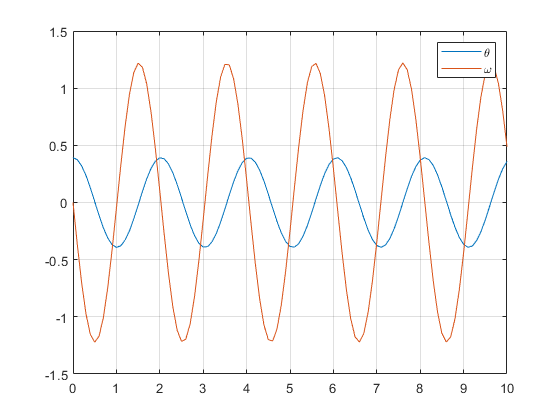

plot(t,y);
grid on;
legend('\theta','\omega');

d = 0.1;
f = @(t,y)[y(2);-(g/1)*sin(y(1))-d*y(2)^2];
y0=[pi/8;0];

[t,y] = ivps(f,0,20,y0,0.1,4)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y =     0.3927    0.3741    0.3198    0.2344    0.1255    0.0031   -0.1211   -0.2350   -0.3274   -0.3891   -0.4142   -0.4002   -0.3484   -0.2639   -0.1550   -0.0325    0.0916    0.2054    0.2983    0.3621    0.3911    0.3831    0.3386    0.2614    0.1583    0.0387   -0.0863   -0.2043   -0.3039   -0.3751   -0.4110   -0.4081   -0.3667   -0.2908   -0.1879   -0.0681    0.0568    0.1747    0.2745    0.3473    0.3866    0.3891    0.3547    0.2863    0.1898    0.0737   -0.0509   -0.1721   -0.2780   -0.3581
         0   -0.3698   -0.7086   -0.9861   -1.1748   -1.2534   -1.2108   -1.0490   -0.7836   -0.4414   -0.0561    0.3346    0.6928    0.9831    1.1764    1.2537    1.2090    1.0498    0.7950    0.4706    0.1065   -0.2664   -0.6171   -0.9150   -1.1315   -1.2430   -1.2352   -1.1063   -0.8682   -0.5446   -0.1679    0.2251    0.5963    0.9091    1.1325    1.2440    1.2338    1.1057    0.8756    0.5682    0.2123   -0.1613   -0.5214   -0.8373   -1.0796   -1.2228   -1.2498   -1.1547   -0.9457   -0

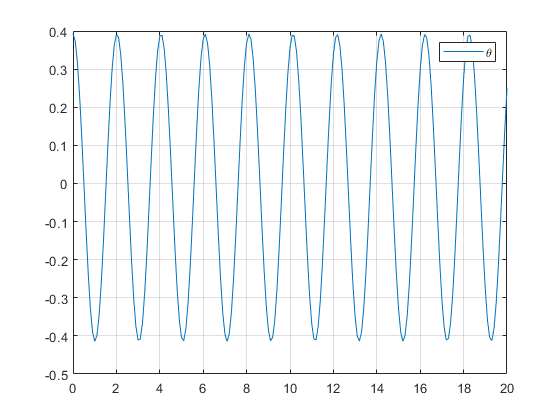

plot(t,y(1,:));
grid on;
legend('\theta','\omega');